# Localization AFM Map Generation

% This code assumes the starting point is a aligned 3D stack of images
% To detect particle and perform alignment see the Particle_detect Workbook

## Load AFM Image

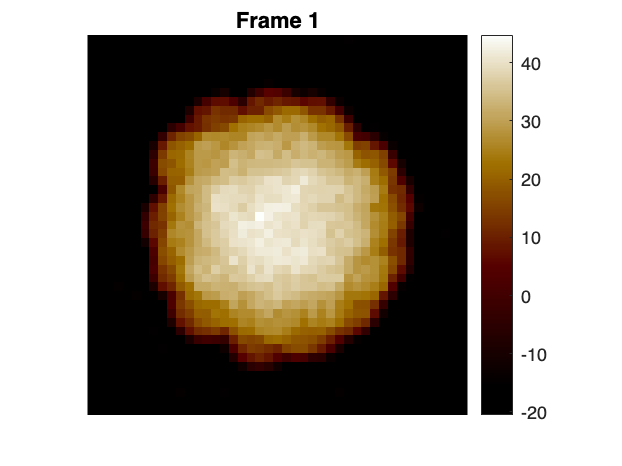

show_frame = 10;
% Read in the AFM image and load the custom colormap LUTs
[im, ImageInfo] = ReadAFMFile('0375 spi_sim 0375.tiff');
load('AFM_luts_full.mat');

figure;
imagesc(im(:,:,show_frame));
axis image off;
afm_colormap('AFM brown')
colorbar;
title('Frame 1');

## Apply Image Filtering

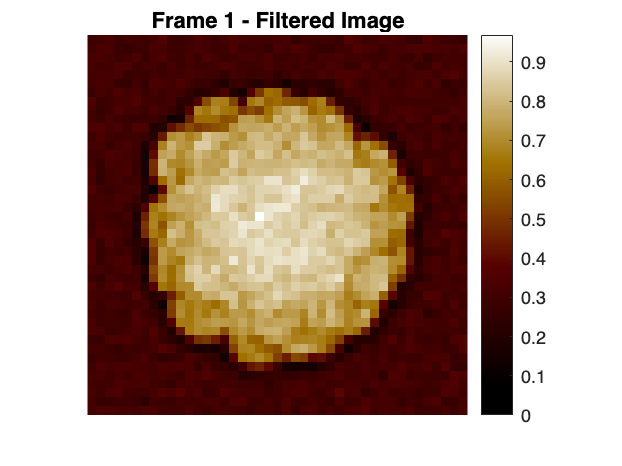

% Apply a combination of Gaussian and Laplacian filtering to enhance features
im2 = filter_movie(im, 'Gaussian', 0.2, 'Laplacian', 50);

%Display filtered movie frame 1
figure;
imagesc(im2(:,:,show_frame));
axis image off;
afm_colormap('AFM brown')
colorbar;
title('Frame 1 - Filtered Image');

## Detect Peaks in Each Frame

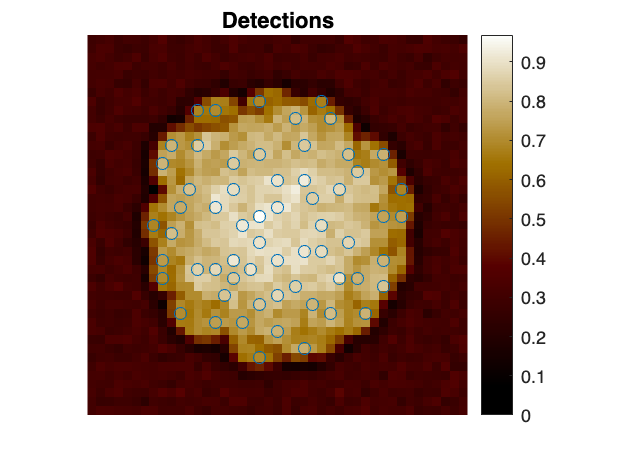

% Loop through each frame in the filtered image stack to find local peaks
LAFM_thresh = 0.5;            % Threshold for feature detection
locs = [];
for i = 1:numel(im2(1,1,:))
    li = Fast_peaks2D(im2(:,:,i), LAFM_thresh, 1);     % Find peaks in 2D
    li = [li, i * ones(numel(li(:,1)), 1)];             % Add frame index
    locs = [locs; li];
end
figure;
imagesc(im2(:,:,show_frame));
axis image off;
afm_colormap('AFM brown')
colorbar;
hold on
pos = locs(:,5) == show_frame; %find value for 1 frame
plot(locs(pos,1),locs(pos,2),'o')
title('Detections');

## Subpixel Localization

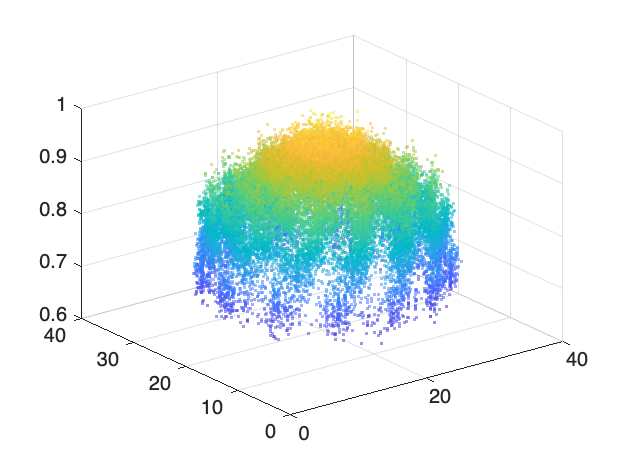

% Use bicubic interpolation to refine the positions of the detected peaks
pixperfeat = 1;               % Pixel scaling for localization
locs = localize(im2, locs, 'bicubic', pixperfeat);

figure;
scatter3(locs(:,1),locs(:,2),locs(:,3),3,locs(:,3),'filled','MarkerFaceAlpha',0.5)

## Render the LAFM Map

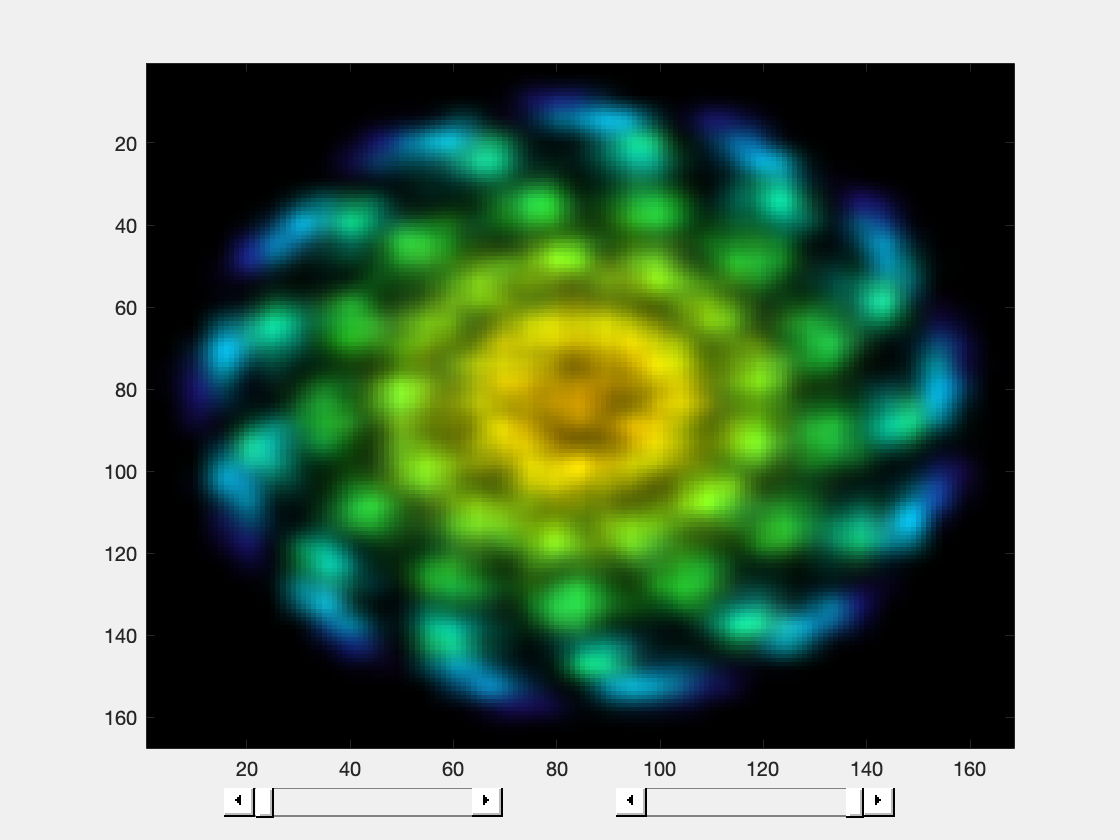

% Render the super-resolved LAFM image using the detected localizations
render_point_sz = 1;
render_image_expansion = 5;
LAFM_full = LAFM_renderer(locs, render_point_sz, render_image_expansion, Rainbow, 0, [], 'Exc outliers'); 

% Plot the reconstructed LAFM image
LAFM_plotter(LAFM_full);

## Calculate Resolution with Fourier Ring Correlation (FRC)

% Measure the spatial resolution of the localization map using FRC
pixpernm = 1;
runs = 20;
[q, frc_mean, av_resolution, sd_resolution] = measureFRC(locs, pixpernm, runs, render_image_expansion);

% Display results
fprintf('Average Resolution: %.2f nm\n', av_resolution);

Average Resolution: 0.40 nm


fprintf('Resolution SD: %.2f nm\n', sd_resolution);

Resolution SD: 0.04 nm
